%Project 9 - Wind Turbine Power Output
%Benjamin Oakes - Engineering Computer Applications

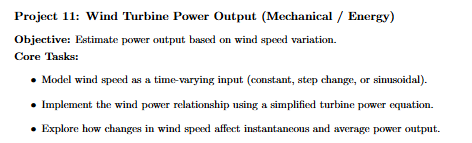

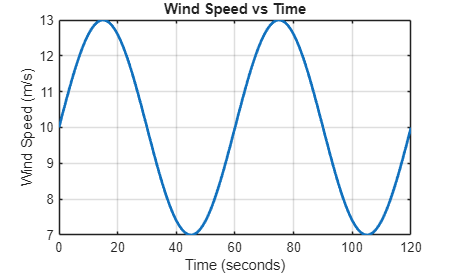


% Clears all variables from the workspace
clear;

% Clears the command window
clc;

% Closes all open figure windows
close all;

% Creates a time vector from 0 to 120 seconds
time = 0:1:120;

% Sets air density in kg/m^3
rho = 1.225;

% Sets turbine blade radius in meters
radius = 15;

% Calculates swept area of the turbine blades
area = pi * radius^2;

% Sets power coefficient
% This represents turbine efficiency
Cp = 0.35;

% Creates wind speed that changes sinusoidally over time
% Average wind speed is 10 m/s
% Wind speed varies by 3 m/s
windSpeed = 10 + 3 * sin(2 * pi * time / 60);

% Calculates turbine power using simplified wind power equation
% P = 0.5 * rho * A * Cp * v^3
powerWatts = 0.5 * rho * area * Cp .* windSpeed.^3;

% Converts power from watts to kilowatts
powerKW = powerWatts / 1000;

% Calculates average power output
averagePowerKW = mean(powerKW);

% Finds maximum power output
[maxPowerKW, maxIndex] = max(powerKW);

% Finds time when maximum power occurs
maxPowerTime = time(maxIndex);

% Finds minimum power output
[minPowerKW, minIndex] = min(powerKW);

% Finds time when minimum power occurs
minPowerTime = time(minIndex);

% Creates first figure
figure;

% Plots wind speed over time
plot(time, windSpeed, 'LineWidth', 2);

% Turns grid on
grid on;

% Adds graph title
title('Wind Speed vs Time');

% Labels x-axis
xlabel('Time (seconds)');

% Labels y-axis
ylabel('Wind Speed (m/s)');

% Saves figure as image
saveas(gcf, 'project11_wind_speed.png');

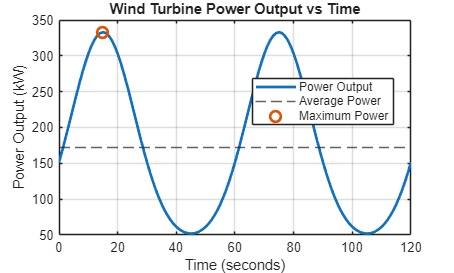


% Creates second figure
figure;

% Plots turbine power output over time
plot(time, powerKW, 'LineWidth', 2);

% Keeps graph active
hold on;

% Draws a horizontal line showing average power
yline(averagePowerKW, '--');

% Marks maximum power point
plot(maxPowerTime, maxPowerKW, 'o', 'MarkerSize', 8, 'LineWidth', 2);

% Turns grid on
grid on;

% Adds graph title
title('Wind Turbine Power Output vs Time');

% Labels x-axis
xlabel('Time (seconds)');

% Labels y-axis
ylabel('Power Output (kW)');

% Adds legend
legend('Power Output', ...
       'Average Power', ...
       'Maximum Power', ...
       'Location', 'best');

% Saves second figure as image
saveas(gcf, 'project11_power_output.png');


% Creates results table
resultsTable = table(time', windSpeed', powerKW', ...
    'VariableNames', ...
    {'Time_seconds', 'WindSpeed_mps', 'Power_kW'});

% Displays table in command window
disp(resultsTable);

    Time_seconds    WindSpeed_mps    Power_kW
    ____________    _____________    ________

          0                10         151.53 
          1            10.314         166.24 
          2            10.624         181.69 
          3            10.927          197.7 
          4             11.22         214.05 
          5              11.5         230.46 
          6            11.763         246.66 
          7            12.007         262.33 
          8            12.229         277.16 
          9            12.427         290.81 
         10            12.598         302.98 
         11            12.741         313.39 
         12            12.853         321.76 
         13            12.934         327.91 
         14            12.984         331.66 
         15                13         332.92 
         16            12.984         331.66 
         17            


% Displays average power
fprintf('Average power output is %.2f kW.\n', averagePowerKW);

Average power output is 171.82 kW.



% Displays maximum power and time
fprintf('Maximum power output is %.2f kW at %.0f seconds.\n', maxPowerKW, maxPowerTime);

Maximum power output is 332.92 kW at 15 seconds.



% Displays minimum power and time
fprintf('Minimum power output is %.2f kW at %.0f seconds.\n', minPowerKW, minPowerTime);

Minimum power output is 51.98 kW at 45 seconds.
